# Mathematical functions

In this section we will take a look at mathematical functions and how to use those.

There are different possibilities to declare and u                    se mathematical functions. For simplification we will just take a look at one specific method. This method is called **anonymous functions.**

**Example**:

sqr = @(x) x.^2; 

The data type of sqr is called function_handle. Where the @ creates the handle and the variables inside the function are the arguments of the function. 

In the End it basically behaves like a regular function (which is the most interesting/important part for us)

sqr(3)

ans = 9


x = -5:0.1:5

x =    -5.0000   -4.9000   -4.8000   -4.7000   -4.6000   -4.5000   -4.4000   -4.3000   -4.2000   -4.1000   -4.0000   -3.9000   -3.8000   -3.7000   -3.6000   -3.5000   -3.4000   -3.3000   -3.2000   -3.1000   -3.0000   -2.9000   -2.8000   -2.7000   -2.6000   -2.5000   -2.4000   -2.3000   -2.2000   -2.1000   -2.0000   -1.9000   -1.8000   -1.7000   -1.6000   -1.5000   -1.4000   -1.3000   -1.2000   -1.1000   -1.0000   -0.9000   -0.8000   -0.7000   -0.6000   -0.5000   -0.4000   -0.3000   -0.2000   -0.1000


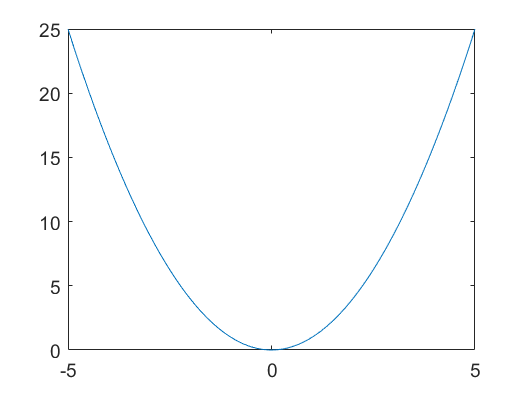

y = sqr(x);
plot(x,y)

we can also use more different variables

**Example**:

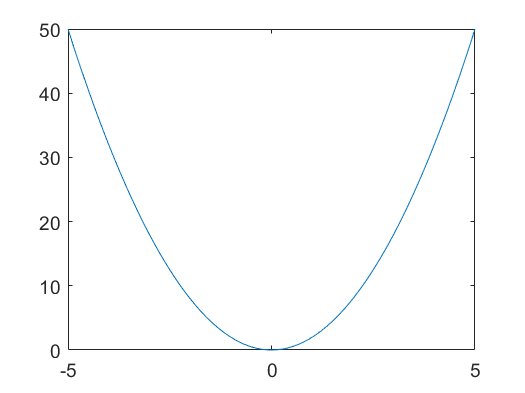

sqrTwo = @(x, a) a.*x.^2; 
a = 2;
plot(x,sqrTwo(x, a))

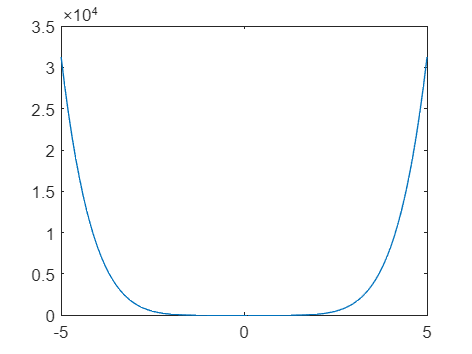

% more than one constant
sqrThree = @(x, a, b) a.*x.^(b.* 2); 
plot(x,sqrThree(x, 2, 3))

better way of doing it:

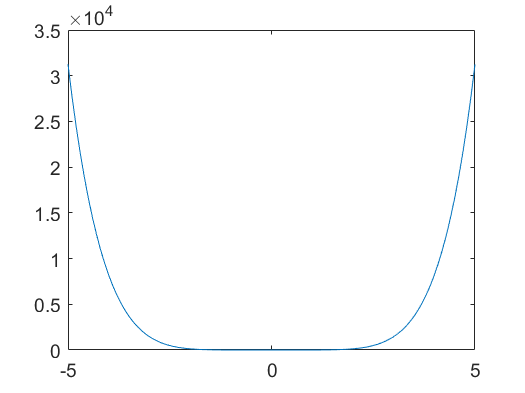

sqrThree = @(x, a) a(1).*x.^(a(2).* 2);
aInput = [2 3];
plot(x,sqrThree(x, aInput))

**Exercise**: Think of your own function with at least 3 constants as input. Create an extra .m file.

**Repetion**: Fitting method `x = lsqcurvefit(fun,x0,xdata,ydata). ``T`his method solves nonlinear equation with a least square algorithm.

Link: [Solve nonlinear curve-fitting (data-fitting) problems in least-squares sense - MATLAB lsqcurvefit - MathWorks Deutschland](https://de.mathworks.com/help/optim/ug/lsqcurvefit.html)

data = readtable('exampleData.csv'); % imports data as table
data = table2array(data); % data is turned numeric
xData = data(:,1);
yData = data(:,2);
plot(data(:,1),data(:,2),'.')
hold on
%  f(x) = a * (x-b)^2 + c
funExample = @(x, xData) x(1).*(xData - x(2)).^2 + x(3) % anonymous functions

funExample = function_handle with value:
    @(x,xdata)x(1).*(xdata-x(2)).^2+x(3)



x0 = [-1 1 1]; %initial values
x1 = lsqcurvefit(funExample,x0,xData,yData)


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


x1 =    -1.0000    4.0000    5.0000


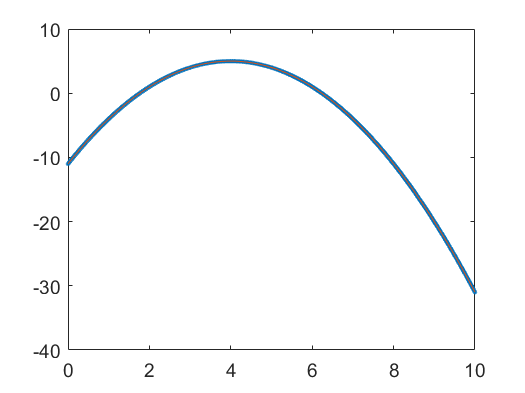


plot(xData, funExample(x1,data(:,1)))
hold off

pause(1)

**Exercise**: (hint: stick closely with the example above)

- import the sin.csv and plot it

- build your own fit function: y = a * sin(x + b)

- use lsqcurvefit() to find the parameters

- plot the data

clear all
data = readtable('sin.csv'); % imports data as table
data = table2array(data); % data is turned numeric
xData = data(:,1);
yData = data(:,2);

plot(xData, yData)
hold on

%  f(x) = a.*sin(xdata + b)
fun = @(x, xdata) x(1).*sin(xdata+x(2))

fun = function_handle with value:
    @(x,xdata)x(1).*sin(xdata+x(2))



x0 = [1 1] ; %initial values
x = lsqcurvefit(fun,x0,xData,yData)


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


x =     1.5000    1.0000


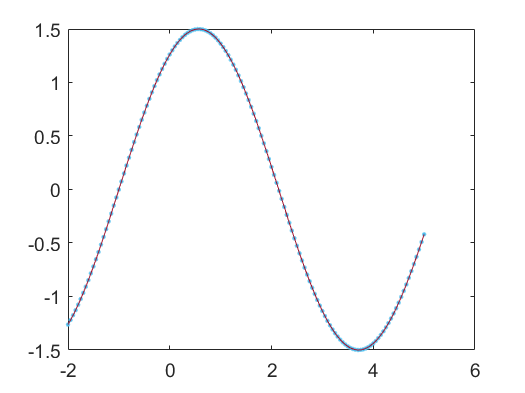


plot(xData, fun(x,xData))

**New:** Find zero with **fzero**() function. With the help of this function, we can find all zero crossings. 

**Link: **[Root of nonlinear function - MATLAB fzero - MathWorks Deutschland](https://de.mathworks.com/help/matlab/ref/fzero.html)

funExample = @(x)funExample(x1,x)

funCrossing = function_handle with value:
    @(z)fun(x,z)


zerosCrossings = fzero(funExample, 1)

zerosCrossings = -1.0000

**Exercise**: 

- Do the same thing with the data of the sin (sin.csv) and find **all** zero crossings. 

- Find the Maximum and the Minimum as well as their indices (and the corresponding x-values)

- **Advanced**: Use the trapz()-function and integral()-function to determine the area bellow the sin function.

funCrossing = @(z)fun(x ,z)

maxima = 1.4997

maxInd = 52

zerosCrossings = fzero(funCrossing, -1)

ans = 0.5500

[maxima, maxInd] = max(fun(x,data(:,1)))

minima = -1.4999

minInd = 115

xData(maxInd)

ans = 3.7000

[minima, minInd] = min(fun(x,data(:,1)))
xData(minInd)


integral2 = -0.6297

integral1 = integral(funCrossing,xData(1), xData(end));
integral2 = trapz(xData, yData);